
clear; clc;

N = 400; nTrials = 1000; trialLen = 100;
%% Initializing the Network properties

noise_window = 100; % in seconds
baseFolder = fullfile(pwd, 'Data', "N" + num2str(N));
net = IzhikevichNetwork(N, 'heterogeneity', true, 'g_ee', 0.5, 'g_ei', 2, 'g_ie', 2, 'ExtoExDegree', 20, 'InhtoExDegree', 5, 'ExtoInhDegree', 5, 'baseFolder', baseFolder);

net.STDP = true;
net.noise = false;

net.sampling_rate = 5000;


n_mems = 5;
for i=1:n_mems

    stim = Stimulation(net, 100, 2, 30, 50, 5);
    net.stimulation = true;
    net.stims = [stim];
    net.run(100000);

    net.stimulation = false;
    net.STDP = false;
    net.noise = true;
    net.run(noise_window*1000);
    net.STDP = true;
    net.noise = false;
end



data = net.getData();
firings = data.firings;


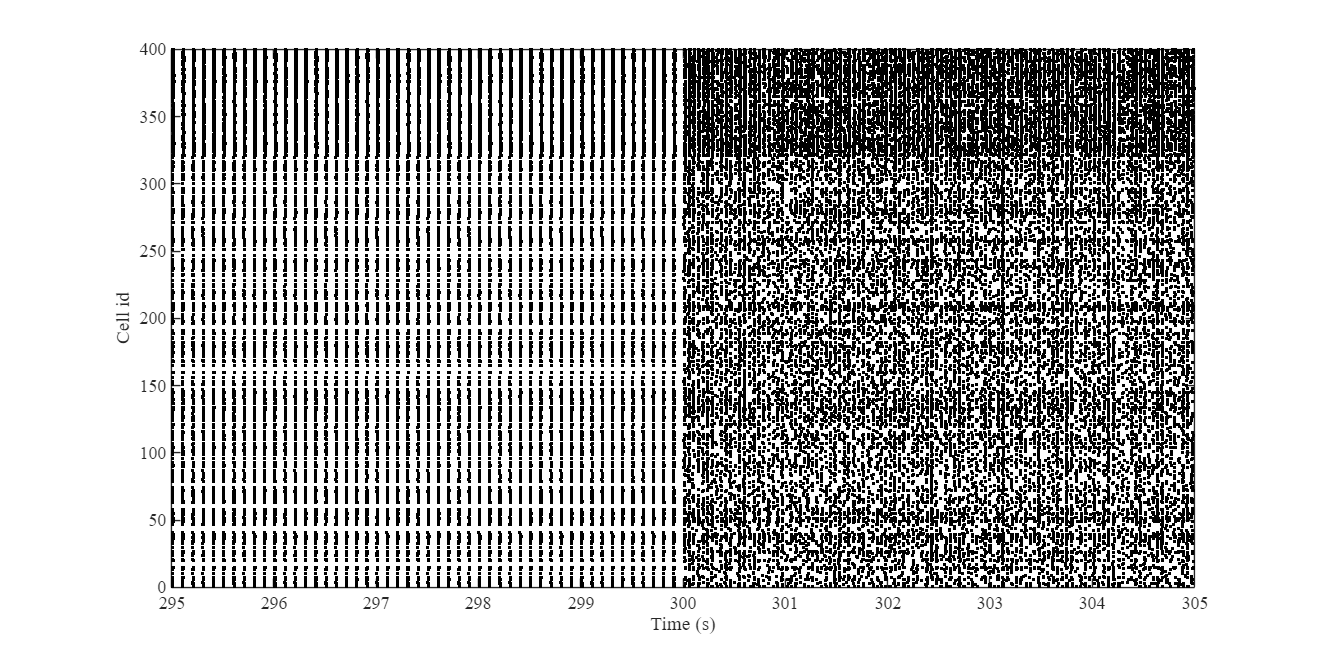

figure(Position=[0, 0, 1200, 600]);
index = (firings(1, :) < 305000) & (firings(1, :) > 295000);
% index = (firings(1, :) < 220000);
plot(firings(1, index)/1000, firings(2, index), 'k.')
xlabel("Time (s)"); ylabel("Cell id")

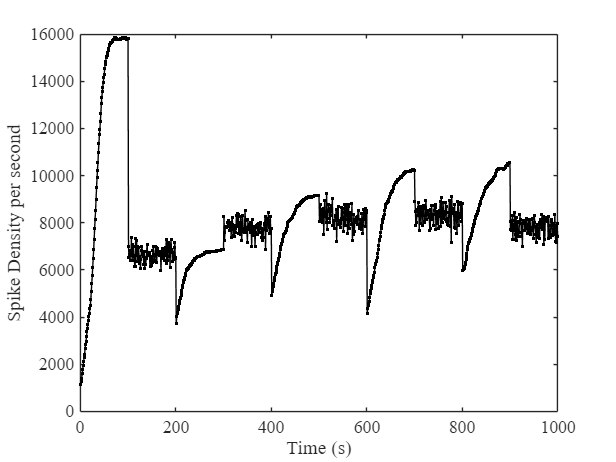


figure; plot(histcounts(firings(1, :), 1000), 'k.-'); 
ylabel("Spike Density per second"); xlabel("Time (s)");

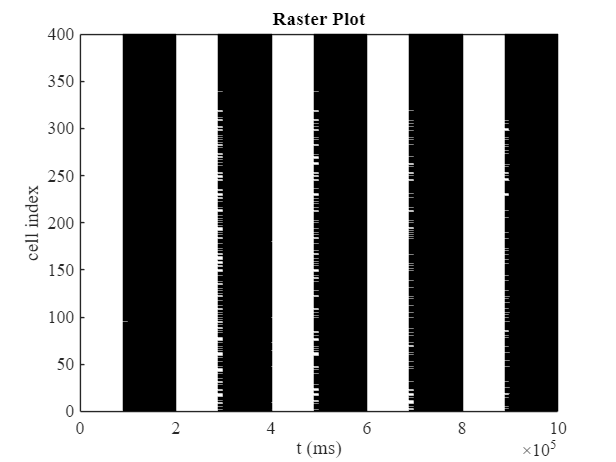

step = 100000 + noise_window*1000;

f = containers.Map();
for i = 1:n_mems
    index1 = (firings(1, :) > step*(i-1)+ 90000 ) & (firings(1, :) < step*(i-1)+100000);
    index2 = (firings(1, :) > step*(i-1)+100000 ) & (firings(1, :) < step*(i-1) + step);
    f(['mem', num2str(i)]) = firings(:, index1);
    f(['noise', num2str(i)]) = firings(:, index2);

end

figure();
ff = cell2mat(f.values());
plot(ff(1, :), ff(2, :), 'k.', MarkerSize=1)
xlabel("t (ms)")
ylabel("cell index")
title("Raster Plot")

bursts = [];
num_burst = containers.Map(f.keys, f.values);
key_list = f.keys;
for key = key_list
    [bursts_temp, fig] = BurstDetector(f(key{1}), [], false, 'All', 3, 3);
    
    bursts = [bursts; bursts_temp];
    num_burst(key{1}) = size(bursts_temp, 1);
end

Detected bursts (start, end) in ms:
   1.0e+04 *

    9.0004    9.0019
    9.0106    9.0118
    9.0205    9.0220
    9.0304    9.0319
    9.0406    9.0418
    9.0505    9.0520
    9.0604    9.0619
    9.0706    9.0718
    9.0805    9.0820
    9.0904    9.0919
    9.1006    9.1018
    9.1105    9.1120
    9.1204    9.1219
    9.1306    9.1318
    9.1405    9.1420
    9.1504    9.1519
    9.1606    9.1618
    9.1705    9.1720
    9.1804    9.1819
    9.1906    9.1918
    9.2005    9.2020
    9.2104    9.2119
    9.2206    9.2218
    9.2305    9.2320
    9.2404    9.2419
    9.2506    9.2518
    9.2605    9.2620
    9.2704    9.2719
    9.2806    9.2818
    9.2905    9.2920
    9.3004    9.3019
    9.3106    9.3118
    9.3205    9.3220
    9.3304    9.3319
    9.3406    9.3418
    9.3505    9.3520
    9.3604    9.3619
    9.3706    9.3718
    9.3805    9.3820
    9.3904    9.3919
    9.4006    9.4018
    9.4105    9.4120
    9.4204    9.4219
    9.4306    9.4318
    9.4405    9.4420
    9

% f = f(:, f(2, :) <= 320);
[features, f_names] = ExtractBurstFeatures(cell2mat(f.values()), bursts);

Burst Features (First Spike Times, Mean-Subtracted and NaN-Imputed):
    Neuron 1 First Spike Time    Neuron 2 First Spike Time    Neuron 3 First Spike Time    Neuron 4 First Spike Time    Neuron 5 First Spike Time    Neuron 6 First Spike Time    Neuron 7 First Spike Time    Neuron 8 First Spike Time    Neuron 9 First Spike Time    Neuron 10 First Spike Time    Neuron 11 First Spike Time    Neuron 12 First Spike Time    Neuron 13 First Spike Time    Neuron 14 First Spike Time    Neuron 15 First Spike Time    Neuron 16 First Spike Time    Neuron 17 First Spike Time    Neuron 18 First Spike Time    Neuron 19 First Spike Time    Neuron 20 First Spike Time


assemblies = features;
X_mean = nanmean(assemblies, 2);  
X_std = nanstd(assemblies, 0, 2); 

assemblies = (assemblies - X_mean) ./ X_std;

% assemblies = [assemblies(100, :); assemblies(200, :); assemblies(300, :); assemblies(301:end, :)];
% dist = squareform(pdist(assemblies, 'correlation'));
f = waitbar(0, "Please wait");
dist = zeros(size(assemblies, 1), size(assemblies, 1));
for i = 1:size(dist,1)
    waitbar((i-1)/size(dist, 1), f, "Please wait")
    for j = i:size(dist,2)
        idx = ~isnan(assemblies(i, :)) & ~isnan(assemblies(j, :));
        if sum(idx) > 50
            dist(i, j) = corr(assemblies(i, idx)', assemblies(j, idx)');
            dist(j, i) = dist(i, j);
        end
    end
end
close(f)


features

features =     5.1000    1.9000    5.1000    7.0000    2.1000    4.5000    6.8000    4.6000         0    5.0000    1.5000    5.5000    6.3000    5.9000    5.3000    4.8000    2.9000    2.6000    6.1000    5.1000    5.4000    4.6000    2.5000    5.0000    5.7000    5.9000    4.3000    4.4000    5.6000    6.8000    2.7000    3.0000    5.2000    6.5000    5.3000    5.3000    5.0000    4.4000    5.6000    2.3000    5.8000    4.4000    5.3000    5.3000    5.2000    4.8000    6.2000    1.8000    5.7000    6.1000
    3.1000       NaN    3.1000    4.9000    0.1000    2.5000    4.7000    2.6000       NaN    3.0000       NaN    3.5000    4.2000    3.9000    3.2000    2.8000    0.9000    0.6000    4.1000    3.0000    3.4000    2.6000    0.5000    3.0000    3.7000    3.9000    2.3000    2.4000    3.6000    4.9000    0.7000    1.0000    3.2000    4.5000    3.3000    3.3000    3.0000    2.3000    3.6000    0.3000    3.8000    2.4000    3.3000    3.3000    3.2000    2.8000    4.1000    1.2000    3.70

# Test the new alg with older 2 for results if they agree or not

dist_new = utils.ComputePearsonSimilarity(features(5, :), features(1, :), 50)

dist_new = single
0.9821

f5_old = features(5, :)

f5_old =     3.1000       NaN    3.1000    5.0000    0.1000    2.5000    4.8000    2.6000       NaN    3.0000       NaN    3.5000    4.2000    3.9000    3.3000    2.7000    0.9000    0.6000    4.1000    3.1000    3.4000    2.6000    0.5000    3.0000    3.7000    3.9000    2.3000    2.4000    3.7000    4.8000    0.8000    1.0000    3.2000    4.5000    3.3000    3.3000    3.0000    2.4000    3.6000    0.3000    3.8000    2.4000    3.3000    3.3000    3.2000    2.8000    4.1000    1.2000    3.7000    4.0000


f1_old = features(1, :)

f1_old =     5.1000    1.9000    5.1000    7.0000    2.1000    4.5000    6.8000    4.6000         0    5.0000    1.5000    5.5000    6.3000    5.9000    5.3000    4.8000    2.9000    2.6000    6.1000    5.1000    5.4000    4.6000    2.5000    5.0000    5.7000    5.9000    4.3000    4.4000    5.6000    6.8000    2.7000    3.0000    5.2000    6.5000    5.3000    5.3000    5.0000    4.4000    5.6000    2.3000    5.8000    4.4000    5.3000    5.3000    5.2000    4.8000    6.2000    1.8000    5.7000    6.1000


save("mahkame.mat", 'f5_old', "f1_old", '-append')
% save("ffff.mat", 'dist', 'dist_new', '-append');

iii = randi(10303); jjj = randi(10303);
utils.ComputePearsonSimilarity(assemblies(iii:iii+2, :), assemblies(jjj:jjj+2, :), 50)

ans = 3×3 single matrix
    0.3067    0.3083    0.2763
    0.3339    0.2990    0.2665
    0.3275    0.2857    0.2730


dist(iii:iii+2, jjj:jjj+2);

% figure;
% histogram(dist(1:100, 1:100))

% figure;
% histogram(utils.ComputePearsonSimilarity(assemblies(1:100, :), assemblies(1:100, :), 50))
dist(1, 5)

ans = 0.9821

% dist_new(1, 5)
bursts_old = bursts;
save("mahkame.mat", 'bursts_old', '-append');

fig = figure(); fig.Position(3:4) = [800, 800]; 

imshow(dist);
colormap('parula');
cb = colorbar();
clim([min(dist, [], 'all'), max(dist, [], 'all')])
xlabel('burst'); ylabel('burst'); cb.Label.String = "Correlation of Intersection";
title("Similarity matrix of Bursts")
% saveas(fig, ['Plots' filesep 'image3.png'])

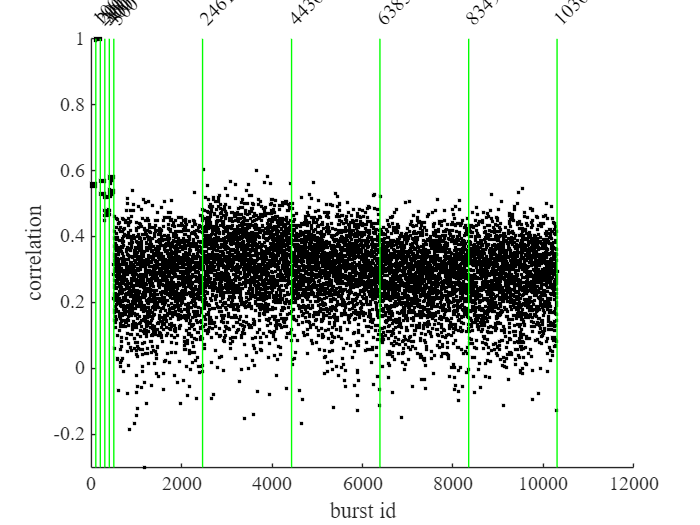


fig = figure(); hold on;
data = dist_new(200, 1:end);
plot(data, 'k.')
counter= 0;
l = num_burst.values;
for b = l(1:end)
    counter = counter + b{1};
    plot(counter*[1, 1], [min(data), max(data)], 'g-')
    text(counter, 1.05*max(data), num2str(counter), "Rotation",45)
    % boxplot(assemblies)
end
ylim([min(data), max(data)])
xlabel("burst id")
ylabel("correlation")

% saveas(fig, ['Plots' filesep 'image4.png'])

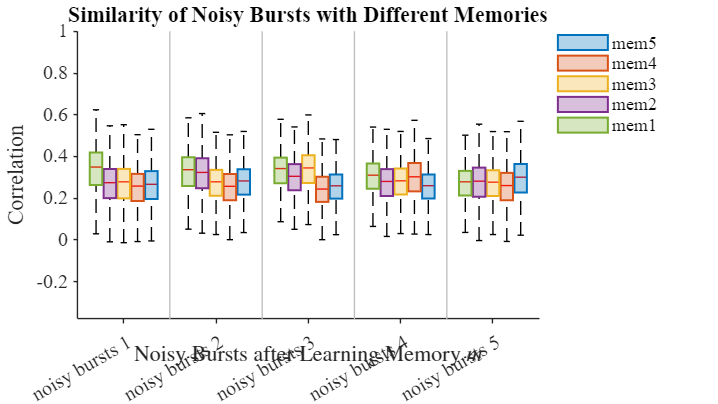


index = [];
n = 0;
for num = num_burst.values
    index = [index; [n + 1, num{1} + n]];
    n = num{1} + n;
end

% Initialize data as a cell array
data = cell(n_mems, n_mems);  
c_label = {};  % Category labels
g_label = {};  % Group labels

% Populate data and labels
for mem = 1:n_mems
    for i = 1:n_mems
        % Extract data for each (mem, i) combination
        temp = dist_new((mem - 1) * 100 + (1:100), index(i+n_mems, 1):index(i+n_mems, 2));
        temp = temp(:)';
        temp = temp(temp ~= 0);

        % Store data in the cell array
        data{i, mem} = temp;  % Ensure each group data is a row vector

        % Define labels
        if mem == 1
            c_label{i} = ['noisy bursts ', num2str(i)];
        end
        g_label{mem} = ['mem', num2str(mem)];
    end
end

% Call the function
fig = figure();
plotGroupedBox(data, c_label, g_label);

% saveas(fig, ['Plots' filesep 'image5.png'])



function plotGroupedBox(data, category_labels, group_labels)
    % plotGroupedBox: Creates a grouped box plot with overlaid scatter points for each group.
    %
    % Parameters:
    %   data - Cell array: {category, group}, each cell is a numeric vector
    %   category_labels - Labels for main categories (x-axis ticks)
    %   group_labels - Labels for each sub-group (used in legend)

    % Check dimensions
    num_categories = length(category_labels);
    num_groups = length(group_labels);

    % Prep
    all_data = [];
    positions = [];
    categories = [];
    groups = [];
    scatter_x = [];
    scatter_y = [];

    offset = 0.15;  % group spacing
    base_pos = 1;
    position_counter = base_pos;

    colors = lines(num_groups);  % assign colors

    % Build data arrays
    for c = 1:num_categories
        for g = 1:num_groups
            group_data = data{c, g};
            if isempty(group_data), continue; end

            x_pos = position_counter + (g - (num_groups + 1) / 2) * offset;

            all_data = [all_data; group_data(:)];
            categories = [categories; repmat(c, length(group_data), 1)];
            groups = [groups; repmat(g, length(group_data), 1)];
            positions = [positions, x_pos];

            scatter_x = [scatter_x, x_pos + (rand(size(group_data)) - 0.5) * offset * 0.6];
            scatter_y = [scatter_y; group_data(:)];
        end
        position_counter = position_counter + 1;
    end

    % --- Plot ---
    hold on;
    box_h = boxplot(all_data, {categories, groups}, ...
        'positions', positions, ...
        'ColorGroup', groups, ...
        'Whisker', 1.5, ...
        'Symbol', '', ...
        'FactorSeparator', 1, ...
        'Widths', offset * 0.9);

    % Color boxes
    h = findobj(gca, 'Tag', 'Box');
    for j = 1:length(h)
        patch(get(h(j), 'XData'), get(h(j), 'YData'), colors(mod(j-1, num_groups)+1, :), ...
            'FaceAlpha', 0.3, 'EdgeColor', colors(mod(j-1, num_groups)+1, :), 'LineWidth', 1.2);
    end

    % % Overlay scatter points
    % scatter(scatter_x, scatter_y, 10, 'k', 'filled', 'MarkerFaceAlpha', 0.3);

    % Axes and Labels
    xticks(base_pos:base_pos+num_categories-1);
    xticklabels(category_labels);
    xtickangle(30);
    ylabel('Correlation', 'FontSize', 14);
    xlabel('Noisy Bursts after Learning Memory $m$', 'Interpreter', 'latex', 'FontSize', 14);
    title('Similarity of Noisy Bursts with Different Memories', 'FontSize', 14);

    % Styling
    set(gca, 'FontSize', 12, 'Box', 'off', 'TickDir', 'out');
    xlim([0.5, position_counter - 0.5]);

    % Legend (dummy lines)
    for g = 1:num_groups
        plot(NaN, NaN, '-', 'LineWidth', 2, 'Color', colors(g, :));
    end
    legend(fliplr(group_labels), 'Location', 'bestoutside', 'Box', 'off');
    hold off;

    % Export if needed
    set(gcf, 'Units', 'inches', 'Position', [1, 1, 8, 4.5]);
end


d



% [~, clusters, ~] = DimensionalityReductionPCA(features, 2, true, 4, f_names);
% figure; hold on;
% plot(clusters, 'ko')
% xlabel("burst id")
% ylabel("cluster id")
% counter = 0;
% 
% for key = num_burst.keys
%     s = key{1};
%     area([counter, counter + num_burst(s)], [4, 4], 'FaceAlpha', 0.3)
%     counter = counter + num_burst(s);
% end


% Select optimal number of clusters (K value) using specified range
fh = @(X,K)(kmeans(X,K,"Distance","cosine"));
eva = evalclusters(features,fh,"CalinskiHarabasz","KList",2:10);
clear fh
K = eva.OptimalK;
clusterIndices = eva.OptimalY;

% Display cluster evaluation criterion values
figure
bar(eva.InspectedK,eva.CriterionValues);
xticks(eva.InspectedK);
xlabel("Number of clusters");
ylabel("Criterion values - calinskiHarabaszCriterion");
legend("Optimal number of clusters is " + num2str(K))
title("Evaluation of Optimal Number of Clusters")
disp("Optimal number of clusters is " + num2str(K));
clear K eva

% Calculate centroids
transformedData = features./sqrt(sum(features.^2,2));
centroids = grpstats(transformedData,clusterIndices,"mean");
clear transformedData

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(features);
clusterMeans = grpstats(score,clusterIndices,"mean");
h2 = gscatter(score(:,1),score(:,2),clusterIndices);
for i2 = 1:numel(h2)
    h2(i2).DisplayName = strcat("Cluster",h2(i2).DisplayName);
end
clear h2 i2 score
hold on
h2 = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h2.DisplayName = "ClusterMeans";
clear h2 clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");